addpath(genpath("MatlabWebSocket"));
clear
clf

server = Server(30000)

server =   Server with properties:

           Port: 30000
         Secure: 0
         Status: 1
    Connections: [0×1 struct]
      ServerObj: [1×1 javahandle_withcallbacks.io.github.jebej.matlabwebsocket.MatlabWebSocketServer]


while(size(server.Connections, 1)<1)
    fprintf("Waiting for SDL to connect...\n");
    pause(2);
end    

Waiting for SDL to connect...
Waiting for SDL to connect...
Waiting for SDL to connect...
Waiting for SDL to connect...
Waiting for SDL to connect...
Waiting for SDL to connect...


fprintf("Ze bluetoot device has uuh... conncetdeh succefally...\n");

Ze bluetoot device has uuh... conncetdeh succefally...


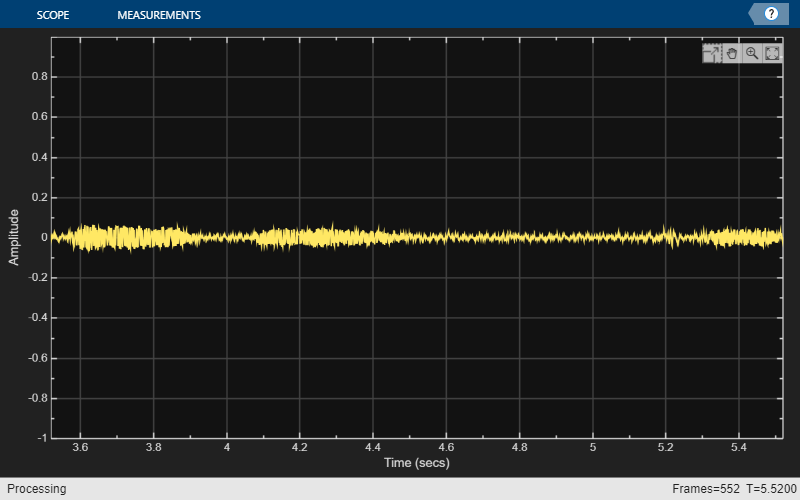

clientCode = server.Connections(1).HashCode;

% Setup audio device reader
fs = 48000; % Sample rate
frameLength = floor(fs/100); % Frame length in samples (10 ms)
overlap = 0; % Overlap in samples
hopSize = frameLength - overlap;
%mic = audioDeviceReader('SampleRate', fs, 'SamplesPerFrame', hopSize);
mic = audioDeviceReader(fs, frameLength, "Device", "Primary Sound Capture Driver");


% Setup timescope for visualization
%scope = timescope('SampleRate', fs, 'TimeSpanSource', 'Property', 'TimeSpan', 5, 'BufferLength', fs*5, 'YLimits', [-0.1 0.1]);
scope = timescope( ...
    'SampleRate',fs, ...
    'TimeSpan',2, ...
    'BufferLength',fs*2*2, ...
    'YLimits',[-1,1], ...
    'TimeSpanOverrunAction',"Scroll");


% Threshold for STE
threshold = 0.01; %0.1, 0.09

STEs = [];
peakIndex = [];

macroFrame=0;
previousSTE=0;

i=1;

% Define the matrix
matrix = [123 456];

% Extract x and y values
x = matrix(1);
y = matrix(2);

% Convert to string in the format X123Y456
outputString = ['X' num2str(x) 'Y' num2str(y)];

% Real-time processing loop
while true
    if(size(server.Connections, 1)<1)
        release(mic);
        server.stop;
        delete(server);
        clear server
        break
    end
    % Read audio frame
    audioIn = mic();
    
    % Compute STE for current frame (simplified, consider implementing a buffer for overlapping frames)
    currentSTE = sum(audioIn.^2) / numel(audioIn); % Simplified STE calculation, scalar

    STEs=[STEs; currentSTE];

    %calculate mean value of latest 10 frames of STEs
    if mod(i,10) == 0
        macroFrame = mean(STEs(1:length(STEs)-1));
    end
    
    peakIndex = [peakIndex; currentSTE - macroFrame];

    % Check against threshold and prepare for localization
    if peakIndex(end) > threshold %peakIndex(end), currentSTE, mean(audioIn)
        server.sendTo(clientCode,outputString);
    end

    i = i+1;

    if size(peakIndex,1) > 20 % Keep only the last 2 seconds of information
         peakIndex = peakIndex(2:end); % Adjust this to manage memory better
         STEs = STEs(2:end);
    end

    % Update timescope
    scope(audioIn);
end